clear all


load frame/1gTruth.mat
g1 = gTruth.DataSource;
tabletrain1  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load frame/2gTruth.mat
g2 = gTruth.DataSource;
tabletrain2  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load frame/3gTruth.mat
g3 = gTruth.DataSource;
tabletrain3  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load frame/aug4gtruth.mat

tabletrain = [tabletrain2;tabletrain1;tabletrain3];

rng(0)
shuffledIndices = randperm(height(tabletrain));
idx = floor(0.7 * height(tabletrain));

trainingIdx = 1:idx;
trainingDataTbl = tabletrain(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.15 * length(shuffledIndices) );
testDataTbl = tabletrain(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
ValidationDataTbl = tabletrain(shuffledIndices(testIdx),:);

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:8));

imdsValidation = imageDatastore(ValidationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(ValidationDataTbl(:,2:8));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,2:8));

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

numAnchors = 7;
anchorBoxes, m = estimateAnchorBoxes(trainingData,numAnchors)

anchorBoxes =     35    20
    19    11
    52    30
    29    16
    86    50
    42    25
    62    37


m =     44    25
    62    37
    52    30
    21    12
    30    16
    87    51
    36    21


featureExtractionNetwork = resnet18;
featureLayer = 'res4b_relu';
numClasses = 7;
%1

inputSize = [224 224 3];
lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);   

augmentedTrainingData = transform(trainingData,@augmentData);

options = trainingOptions('sgdm',...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 3, ...
    'MaxEpochs',2,...
    'MiniBatchSize',16,...
    'ExecutionEnvironment','gpu',...
    "Plots","training-progress",...
    "ValidationData",validationData);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Batuhan
* Berkant
* Damla
* Enes
* Erdem
* Muhammed
* Omer

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.56 |         0.65 |       0.3123 |       0.4234 |          0.0010 |
|       1 |          50 |       00:00:25 |         0.59 |         0.64 |       0.3428 |       0.4153 |          0.0010 |
|       1 |         100 |    

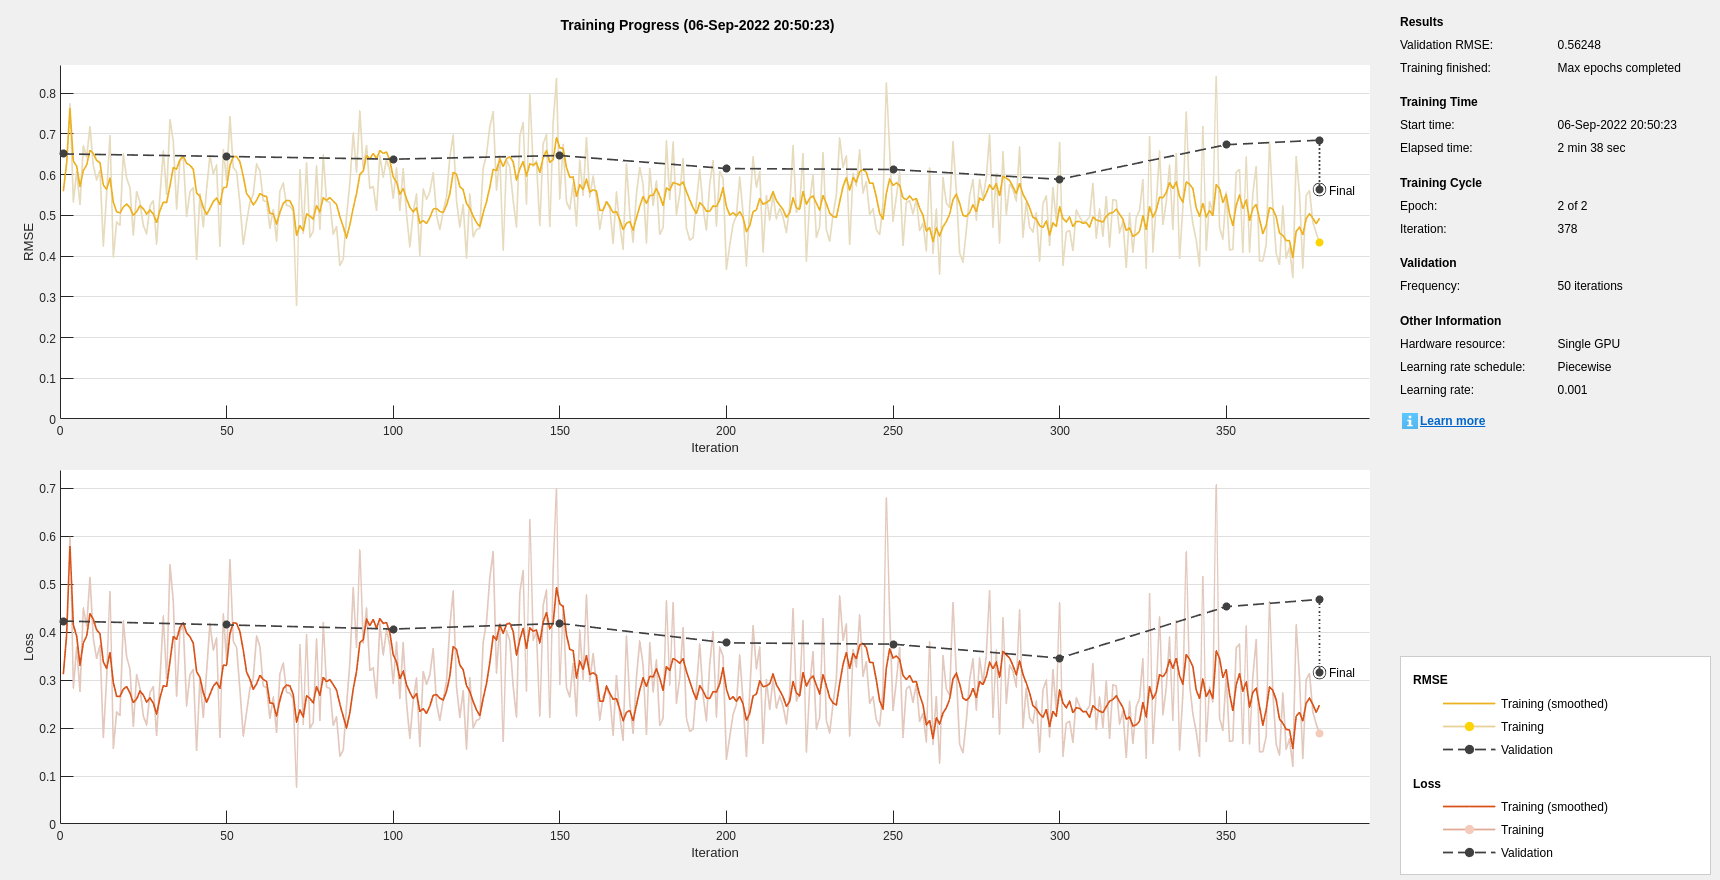

Detector training complete.
*************************************************************************



[detector, info] = trainYOLOv2ObjectDetector(augmentedTrainingData ,detector,options);

 detectionResults = detect(detector,testData,'MinibatchSize',2);   

Error using vision.internal.cnn.validation.checkDetectionInputDatastore (line 18)
The detection data input must be a numeric array or a datastore.

Error in yolov2ObjectDetector/parseDetectInputs (line 514)
                samp

[ap, recall, precision] = evaluateDetectionPrecision(detectionResults,testData,0.3);

[am, fppi, missRate] = evaluateDetectionMissRate(detectionResults, testData);

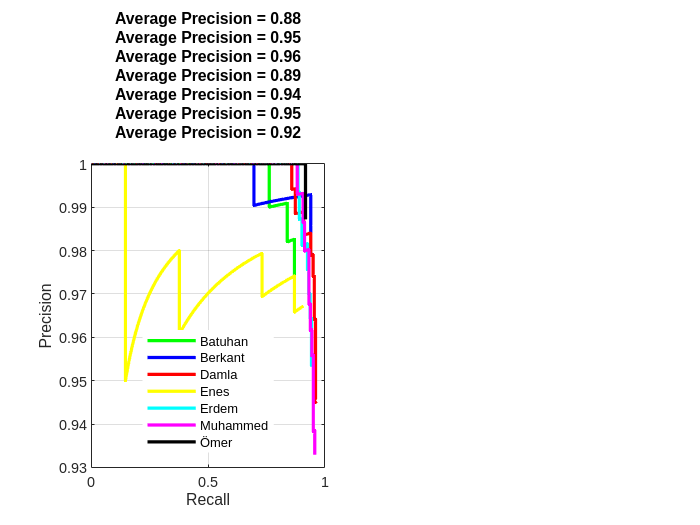

subplot(1,2,1);
plot(recall{1,1},precision{1,1},'g-','LineWidth',2, "DisplayName","Batuhan");
hold on;
plot(recall{2,1},precision{2,1},'b-','LineWidth',2, "DisplayName",'Berkant');
hold on;
plot(recall{3,1},precision{3,1},'r-','LineWidth',2, "DisplayName",'Damla');
hold on;
plot(recall{4,1},precision{4,1},'y-','LineWidth',2, "DisplayName",'Enes');
hold on;
plot(recall{5,1},precision{5,1},'c-','LineWidth',2, "DisplayName",'Erdem');
hold on;
plot(recall{6,1},precision{6,1},'m-','LineWidth',2, "DisplayName",'Muhammed');
hold on;
plot(recall{7,1},precision{7,1},'k-','LineWidth',2, "DisplayName",'Ömer');
hold off;

xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.2f\n', ap))
legend('Location', 'best');
legend('boxoff')
grid on

## Performans Tablo

%figure
%plot(recall,precision)
%xlabel('Recall')
%ylabel('Precision')
%grid on
%title(sprintf('Average Precision = %.2f', ap))

## Tekli Performans Kontrol

img = imread('C:\Users\Batu\Desktop\dji_tello_face_detect_aiis\data_collect\data\resized_1-20220308T192705Z-001\resized_1\01138.jpg');
[bbox, score, label] = detect(detector, img)
detectedI = insertObjectAnnotation(img,'Rectangle',bbox,cellstr(label));
figure
imshow(detectedI)

## Etiket Sayma


%%A = table2array(trainingDataTbl(:,5));
%matcell = cell2mat(A);
%size(matcell)

